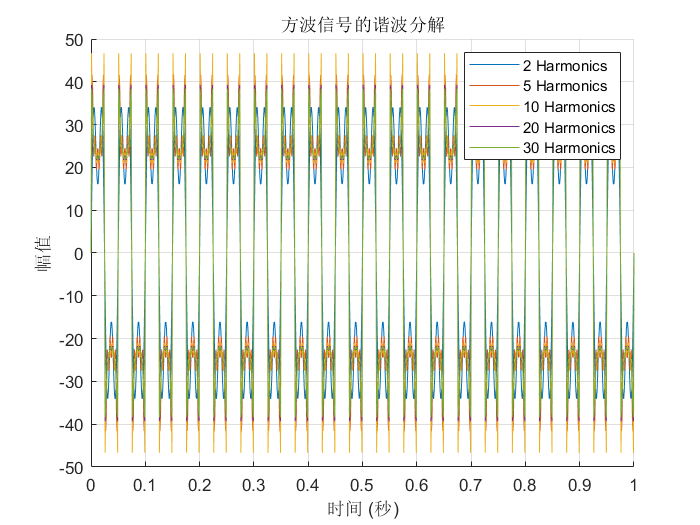

% 设置参数  
Fs = 1000; % 采样频率  
t = 0:1/Fs:1; % 时间向量  
Amplitude = 5; % 幅值  
Frequency = 20; % 频率  

% 创建方波的基频正弦波  
square_wave = Amplitude * square(2 * pi * Frequency * t);  

% 不同数量正弦波的阶数  
harmonics = [2, 5, 10, 20, 30];  %储存不同数量的谐波

% 创建图形  
figure;  
hold on;  

for n = harmonics  
    % 计算方波信号  
    signal = zeros(size(t));  
    for k = 1:n     %遍历所需的谐波数量，生成每个信号，并将其绘制到同一图中
        % 每个正弦波的频率  
        freq_k = (2*k - 1) * Frequency; % 采用奇次谐波  
        signal = signal + (Amplitude / k) * sin(2 * pi * freq_k * t); % 按照傅里叶级数叠加  
    end  
    % 标准化（归一化）信号  
    signal = (4 * Amplitude / pi) * signal;   
    % 绘制信号  
    plot(t, signal, 'DisplayName', sprintf('%d Harmonics', n));  
end  

% 设置图形属性  
title('方波信号的谐波分解');  
xlabel('时间 (秒)');  
ylabel('幅值');  
legend show;  %清晰地展示每个信号
grid on;  
hold off;

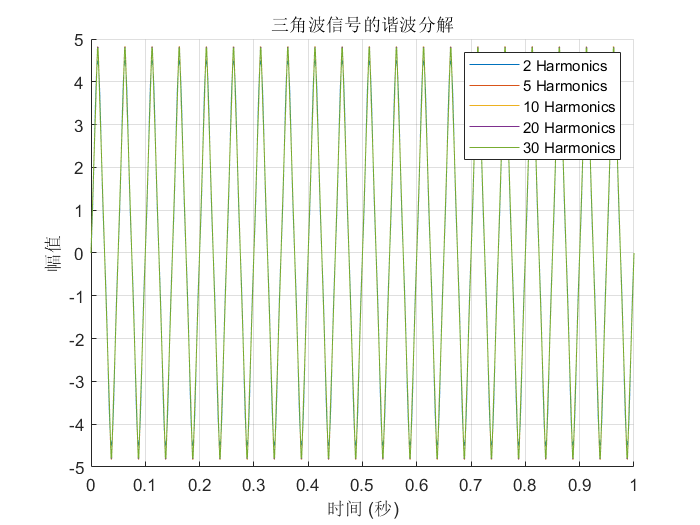

% 设置参数  
Fs = 1000; % 采样频率  
t = 0:1/Fs:1; % 时间向量  
Amplitude = 5; % 幅值  
Frequency = 20; % 频率  

% 训练三角波的基频正弦波  
triangular_wave = Amplitude * sawtooth(2 * pi * Frequency * t, 0.5);  

% 不同数量正弦波的阶数  
harmonics = [2, 5, 10, 20, 30];  

% 创建图形  
figure;  
hold on;  

for n = harmonics  
    % 初始化信号  
    signal = zeros(size(t));  
    for k = 1:n  
        % 每个正弦波的频率 (奇次谐波)  
        freq_k = (2*k - 1) * Frequency;   
        % 计算正弦波并加到信号中，注意正弦波的幅值要按照傅里叶级数叠加  
        signal = signal + (Amplitude * (8 / (pi^2)) * ((-1)^(k+1) / ((2*k - 1)^2))) * sin(2 * pi * freq_k * t);   
    end  
    % 绘制信号  
    plot(t, signal, 'DisplayName', sprintf('%d Harmonics', n));  
end  

% 设置图形属性  
title('三角波信号的谐波分解');  
xlabel('时间 (秒)');  
ylabel('幅值');  
legend show;  
grid on;  
hold off;